# Virus Model (Group 65)

Table of contents

#### BEFORE RUNNING:

Requires **ALL **files within "modular_version" folder on github.

## **Introduction (Problem)**

Inspired by COVID-19, our project will model a mobilised infection propagation of random human movement, emulated by a 2D dimensional frame. The model will begin with a set number of infected individuals within the city (referred to as agents). We will then use a combination of random walks and celluar automata to display the infection status and movement of the disease within a video model. Cellular automata parameters will be applied between each step in the random walk. Our project aims to extend cellular automata by implementing multiple states (Susceptible, Infected, Recovered, Dead). A combination of a third dimension will be implemented with information that indicates the state of the pixels/humans. This third dimension allows a dynamic probability weighting depending on the prior and current conditions of the particle (number of Moore neighbouring infected particles, outer Moore neighbouring particles, times recovered from previous infections, level of susceptibility etc.). The solution will be presented as an animated 2D plot containing the evolution of particle states. After, an SIR model is generated from the model's data. An SIR model (with a constant population), involves the graphing of susceptible individuals (S) as they become infected and move into the infected class (I). After some period of time, infected individuals recover and move into the recovered (or immune) class (R). This model will be compared against a COVID-19 SIR model, for example, to evaluate the reasonableness of the solution.

## **Set up (Solution methods)**

Our population will be a random walk model of 50 steps and 100 particles. The agents (particles) in this model will have 4 stages of infection, these stages will be moved through based on an agents proximity to another infected agent and the probability of death. 5 agents will start off infected. The remaining variables required are listed and the intial parameters are being used. 

Let us assign these variables for our solution in the workspace.

% Initialisation
gridSize = 100;              % The size of the random walks grid
nAgents = 100;               % The number of agents (particles) for the random walks model
infectionDuration = 7;       % This is the infection duration using steps
immunityDuration = 8;        % This is the immunity duration using steps
p0 = 1;                      % The intial probability of infection 
nSteps = 50;                 % The number of steps for the random walks model (time unit)
videoFile ='crenstat';       % The video for the graph / model
neighborhoodType = 'Moore';  % The type of celluar automata cells that can infect (i.e 8 surronding cells)
infectionRadius = 2;         % The infection radius of an agent
visualizationType = 1;       % The display type of the model
reinfectionProbBase = 0.01;  % The probability of reinfection
deathProbBase = 0.02;        % The probability of death

Now let us use these parameters to run our solution.

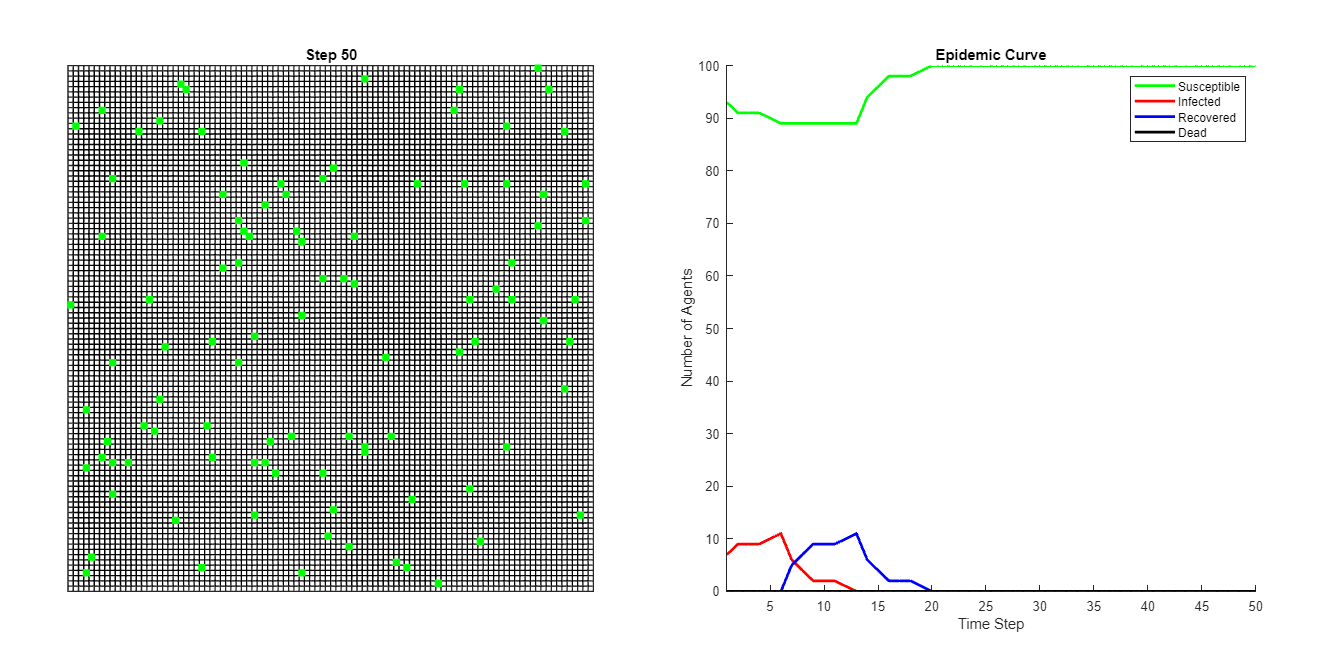

Video saved as crenstat
Total simulation time: 18.0611 seconds


epidemic_simulation(gridSize, nAgents, infectionDuration, immunityDuration, p0, nSteps, videoFile, neighborhoodType, infectionRadius, visualizationType, reinfectionProbBase, deathProbBase)

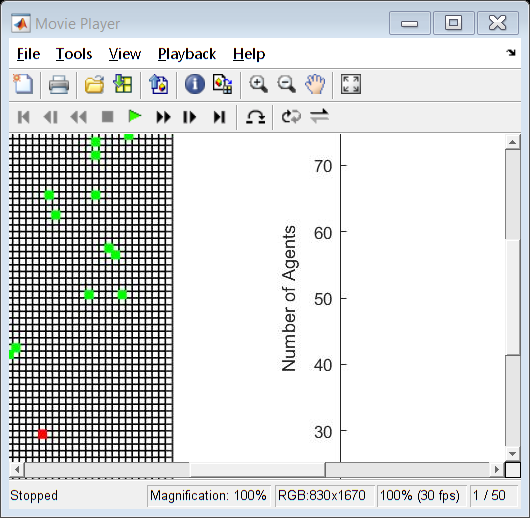

implay('crenstat.avi')

As can be seen above a random walks model and a corresonding graph of the infection stages is displayed. However these parameters are not all that accurate to real life so lets change the parameters to better model a real world scenario.

calebs code

## **Next Step (Results)**

Now let us compare this solution with a SIR simulation to see how successful this model was.

Load simulation

As you can see by comparison .. 

## **Technical Explanation of Code**

### **Random walks**

A basic random walks model was used as a base of human civilisation. The model consists of steps, agents (particles) and the size of the grid.

### **Celluar Automata**

We used cellular automata to represent stages of infection of the human particles shown in the random walks model....

### **Extension**

Our project extends cellular automata by implementing multiple states (empty space, infected human, uninfected human). Also there will be an implemented infection radius for the particles within the simulation. As well as resistance of (...) against catching the infection again once an individual has recovered from the diesease